% EDP tutorial with a 2d example
% clear all
%close all
rng('default');
rng(1);

% time-series generation
disp('Data generation and structure')

Data generation and structure


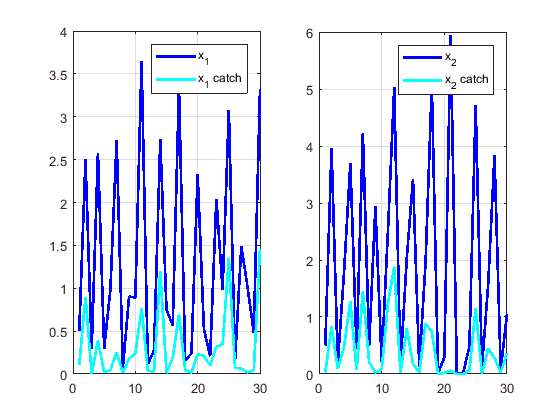


T = 30;

% default EDM structure
[mdlstruct] = init_mdl_struct(2); % the input is the number of species

% data generation using a ricker model
% param={[0.1 0.1],[3 0.5; 0.8 3],[3 3]}; % ricker model parameters
param={[0.1 0.1],[2 0.5; -0.3 2],[3 3]}; % ricker model parameters
mdlstruct.model = @(x,u,is_det) dyn_ricker(x,u,is_det,param);


% random control between 0 and 0.5
u = rand(T,2)/2;

% data generation
[mdlstruct.data,mdlstruct.control_data] =  generate_data(mdlstruct.model,[0.5 0.5],u,T);

%different kinds of control exist, we need to specify which one we use here
mdlstruct.control_type =  'rate';
mdlstruct.control_param =  [1 1]; % both  dimensions are controlled

% data display
data_show(mdlstruct)

% GP regression
disp('GP fitting')

GP fitting


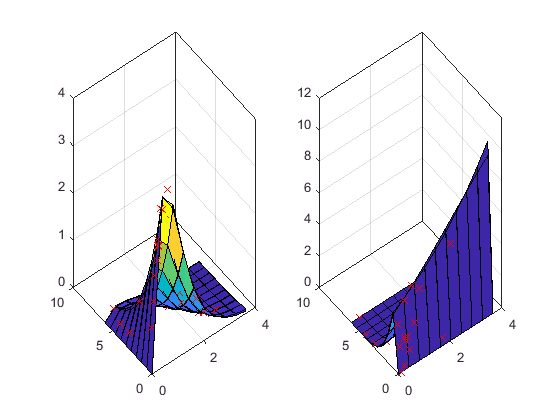

% this step can be skipped if a model already exists, otherwise a GP is
% fitted to the data
% fills the field mdlstruct.model with the fitted gp
% fills the field mdlstruct.model_stats with statistics computed during the
% GP regression

% default gp structure
mdlstruct.gp = init_gp();

% we now fit the gp with the data in mdlstruct
mdlstruct = fit_gp(mdlstruct);


gp_show(mdlstruct)

% Optimal control problem
disp('Optimal control problem structure')

Optimal control problem structure


% Discount factor
optstruct.discount_factor=0.95;

% Objective weights
optstruct.weights = [0.5 0.5];


% Reward function
% The instantaneous reward function is a handle function.
% The input are the current variables, the controls and the weight for each
% dimension
% The output are the total weighted reward, the unweighted reward on each
% dimension, and the weighted reward on each dimension

%>>> Example 1 <<<<
% use of an existing function
optstruct.reward = @(x,u,w) reward_harvest_all(x,u,w);

% Temporal difference learning
disp('EDP using Temporal difference learning')

EDP using Temporal difference learning


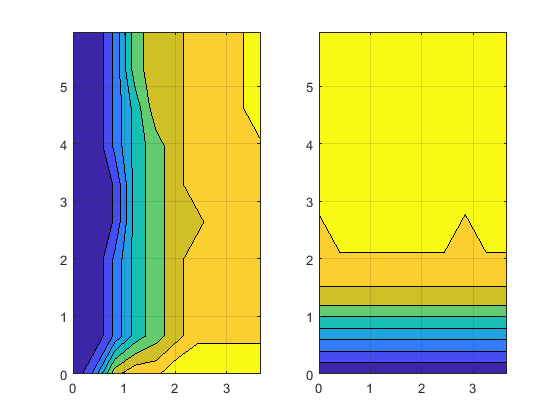

% default  td structure
dpstruct=init_td(mdlstruct);

%  run the td algorithm, using the gp regression
 [dpstruct] = td_learning(mdlstruct,optstruct,dpstruct,'gp');

 % control maps
td_show(mdlstruct,optstruct,dpstruct)


% controlled trajectories
t_max = 50;
n_traj = 10;
start_x = 'last';
traj = sim_trajectories(mdlstruct,optstruct,dpstruct,t_max,n_traj,start_x);

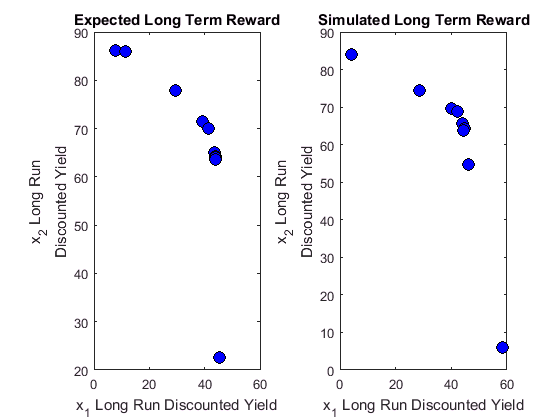

% Pareto front
disp('Pareto front')
n_pareto = 10;
pareto = pareto_front(mdlstruct,optstruct,dpstruct,n_pareto,'gp');


% % control map for different Pareto weights
% td_show(mdlstruct,pareto.optstruct{1},pareto.dpstruct{1})
% td_show(mdlstruct,pareto.optstruct{end},pareto.dpstruct{end})
